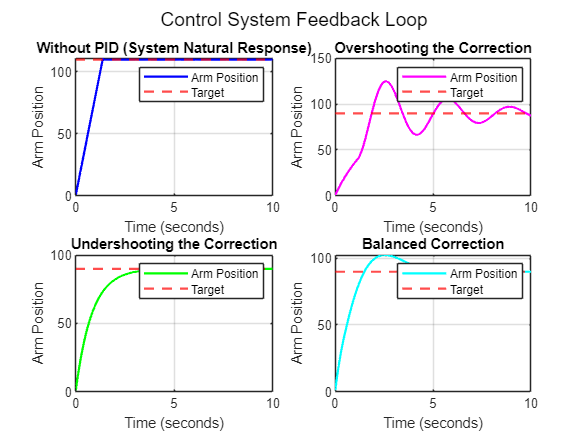

% Set up simulation parameters
target = 90;  % Setpoint for the arm position

% Create figure for subplots
figure;
% Set main title for the subplots
sgtitle('Control System Feedback Loop');
%% Subplot 1: Without PI (System Natural Response)
subplot(2,2,1);
% Set up parameters for subplot 1
armPot = zeros(size(time));  % Reset arm position array
plateau_time = 5; % Time at which to plateau

for i = 1:numel(time)
    % Calculate error
    if i < 2
        armPot(i) = 1;  % Initialize arm position
    end
    
    % Simulate arm movement without PID (system natural response)
    if i < plateau_time / 0.025
        if armPot(i) < 110 % Overshoot to 110
            armPot(i+1) = armPot(i) + 2;  % Simulate movement towards target
        else
            armPot(i+1) = 110;  % Plateau at 110
        end
    else
        armPot(i+1) = 110;  % Plateau at 110 for the remaining time
    end
end

% Plot arm position over time without PID (system natural response)
plot(time(1:i), armPot(1:i), 'b', 'LineWidth', 1.5); % Adjusting plot limits
hold on;
yline(110, 'r--', 'LineWidth', 1.5); % Labeling the target
title('Without PID (System Natural Response)');
xlabel('Time (seconds)');
ylabel('Arm Position');
legend('Arm Position', 'Target');
grid on;
hold off;




%% Subplot 2: Overshooting the Correction
subplot(2,2,2);
% Set up parameters for subplot 2
kP_2 = .5;     % Proportional gain for subplot 2
kI_2 = 0.05;    % Integral gain for subplot 2

armPot = zeros(size(time));  % Reset arm position array
Integral = 0;  % Reset integral term

for i = 1:numel(time)
    % Calculate error
    if i < 2
        armPot(i) = 1;  % Initialize arm position
    end
    
    % Calculate error
    error = target - armPot(i);
    
    % Update integral term
    if abs(error) < 50  % PID_INTEGRAL_LIMIT
        Integral = Integral + error;
    else
        Integral = 0;
    end
    
    % Calculate motor power (with too much correction)
    motorPower = kP_2 * error + 2*kI_2 * Integral; % Increasing the I term for instability
    
    % Apply limits to motor power
    if motorPower > 127
        motorPower = 127;
    elseif motorPower < -127
        motorPower = -127;
    end
    
    % Update arm position (simulate motor movement)
    armPot(i+1) = armPot(i) + motorPower * 0.025;  % Assuming 50 Hz control loop
end

% Plot arm position over time with overshooting the correction
plot(time, armPot(1:end-1), 'm', 'LineWidth', 1.5);
hold on;
yline(target, 'r--', 'LineWidth', 1.5); % Labeling the target
title('Overshooting the Correction');
xlabel('Time (seconds)');
ylabel('Arm Position');
legend('Arm Position', 'Target');
grid on;
hold off;

%% Subplot 3: Undershooting the Correction
subplot(2,2,3);
% Set up parameters for subplot 3
kP_3 = 1.2;     % Proportional gain for subplot 3
kI_3 =0;    % Integral gain for subplot 3

armPot = zeros(size(time));  % Reset arm position array
Integral = 0;  % Reset integral term

for i = 1:numel(time)
    % Calculate error
    if i < 2
        armPot(i) = 1;  % Initialize arm position
    end
    
    % Calculate error
    error = target - armPot(i);
    
    % Update integral term
    if abs(error) < 50  % PID_INTEGRAL_LIMIT
        Integral = Integral + error;
    else
        Integral = 0;
    end
    
    % Calculate motor power (undershooting the correction)
    motorPower = kP_3 * error + kI_3 * Integral; % Decreasing the P term for undershooting
    
    % Apply limits to motor power
    if motorPower > 127
        motorPower = 127;
    elseif motorPower < -127
        motorPower = -127;
    end
    
    % Update arm position (simulate motor movement)
    armPot(i+1) = armPot(i) + motorPower * 0.025;  % Assuming 50 Hz control loop
end

% Plot arm position over time undershooting the correction
plot(time, armPot(1:end-1), 'g', 'LineWidth', 1.5);
hold on;
yline(target, 'r--', 'LineWidth', 1.5); % Labeling the target
title('Undershooting the Correction');
xlabel('Time (seconds)');
ylabel('Arm Position');
legend('Arm Position', 'Target');
grid on;
hold off;

%% Subplot 4: P and I Control Together
subplot(2,2,4);
% Set up parameters for subplot 4
kP_4 = 1.3;     % Proportional gain for subplot 4
kI_4 = 0.03;    % Integral gain for subplot 4

armPot = zeros(size(time));  % Reset arm position array
Integral = 0;  % Reset integral term

for i = 1:numel(time)
    % Calculate error
    if i < 2
        armPot(i) = 1;  % Initialize arm position
    end
    
    % Calculate error
    error = target - armPot(i);
    
    % Update integral term
    if abs(error) < 50  % PID_INTEGRAL_LIMIT
        Integral = Integral + error;
    else
        Integral = 0;
    end
    
    % Calculate motor power (P and I control together)
    motorPower = kP_4 * error + kI_4 * Integral;
    
    % Apply limits to motor power
    if motorPower > 127
        motorPower = 127;
    elseif motorPower < -127
        motorPower = -127;
    end
    
    % Update arm position (simulate motor movement)
    armPot(i+1) = armPot(i) + motorPower * 0.025;  % Assuming 50 Hz control loop
end

% Plot arm position over time with P and I control together
plot(time, armPot(1:end-1), 'c', 'LineWidth', 1.5);
hold on;
yline(target, 'r--', 'LineWidth', 1.5);
title('Balanced Correction');
xlabel('Time (seconds)');
ylabel('Arm Position');
legend('Arm Position', 'Target');
grid on;
hold off;